clear;

%Default values if not entered in GUI popup
absorbanceSelected = 0;
plotsSelected = 0;
KineticTime = [];
smoothStepsize = 50; %smooth data increment (tied to spectrometer spectral resolution)
timeRange = [];
numdata = 12; %set based on how many files to go through
% spacingtime = 1;
offset = 0; %set offset to ignore this many absorbance plots at start of experiment
offset = offset + 1;
timestepSet = 1; %set a timestep to skip absorbance plots if desired


resultVariables = GUIScript(); %Get values from GUI popup

%If press cancel, stop code
if isempty(resultVariables)
    disp('Canceled');
    return;
end

%Save variables from GUI popup
absorbanceSelected = resultVariables.absorptionYN;
plotsSelected = resultVariables.plotsYN;
Sample = cell2mat(resultVariables.SampleName);
Solvent = cell2mat(resultVariables.SolventName);
ConcentrationAmount = cell2mat(resultVariables.ConcentrationNum);
ConcentrationUnits = resultVariables.SelectedUnit;
StartABSWL = cell2mat(resultVariables.StartWL);
EndABSWL = cell2mat(resultVariables.EndWL);
KineticTime = str2double(cell2mat(resultVariables.KinTime));
wavePos = str2double(cell2mat(resultVariables.WavePosition));
timeRange = str2double(cell2mat(resultVariables.TotalTime));
ConcentrationOptions = {'M', 'mM', 'uM', 'nM'};
ConcentrationValues = {1, 1E-3, 1E-6, 1E-9};
if any(strcmp(ConcentrationUnits, ConcentrationOptions))
    concentrationPosition = find(strcmp(ConcentrationUnits, ConcentrationOptions));
    concentration = ConcentrationValues{concentrationPosition};
else
    disp('No concentration set.');
    concentration = 1
end

Solventname = ConcentrationAmount + " " + ConcentrationUnits + " " + Sample + " in " + strrep(Solvent,  '_', ' ');
Solventfilename = ConcentrationAmount + "" + ConcentrationUnits + "" + Sample + "" + strrep(Solvent,  '_', '');

%Initial concentration (note does not factor in chromophores for tethered molecules)
initialConcentration = concentration*str2double(ConcentrationAmount);

%folder processing, finding data based on file heirachy (save under: Samplename/SamplenameSolventConcentration/)
curfolder = pwd;
folderPath = fullfile([curfolder, '/', Sample, '/', Sample, Solvent, ConcentrationAmount, ConcentrationUnits]);
folddirInfo = dir(fullfile(folderPath, '*'));
folddirInfo = folddirInfo(~ismember({folddirInfo.name}, {'.', '..'}));
folders = folddirInfo([folddirInfo.isdir]);
if (isempty(numdata) || isnan(numdata) || numdata > length(folders))
    numdata = length(folders); %if number of data is not set or greater than folders, set to # of folders
end
excitationWLs = cell(1:length(numdata));
foldername = cell(1:length(numdata));
fileData = cell(1:length(numdata));
filePattern = '*.txt';
fileList = cell(1:length(numdata));

%check for laser powers in csv file, needs to be saved in folder with columns in order: wavelength, laser E before, laser E before Std D, laser E after, laser E after Std D
fileNameLaserPower = fullfile([Sample, Solvent, ConcentrationAmount, ConcentrationUnits, 'LaserPowers.csv']);
if exist(fullfile(folderPath, fileNameLaserPower), 'file')
    fileDataLaser = importdata(fullfile(folderPath, fileNameLaserPower));
    LaserPulseEBefore = fileDataLaser.data(1:end,1);
    LaserPulseErrorBefore = fileDataLaser.data(1:end,2);
    LaserPulseEAfter = fileDataLaser.data(1:end,3);
    LaserPulseErrorAfter = fileDataLaser.data(1:end,4);
    CuvetteTransmission = 0.85; %set cuvette transmission here, can add wavelength dependent vector in future if not using quartz cuvettes
    pathlength = 1.5; %set pathlength based on sample length
    PhotonEnergyMean = (LaserPulseEBefore(1:numdata)+LaserPulseEAfter(1:numdata))/2;
end

%loop through each folder containing a number of absorbance files over time for that given experiment
for i = 1:numdata
    foldername = folddirInfo(i).name;
    expressionWLs = strcat(Sample, Solvent, ConcentrationAmount, ConcentrationUnits, '(\d{1,})nm[A-Z]'); %grab wavelength and ID
    excitationWLs{i} = cell2mat(regexp(foldername, expressionWLs, 'tokens', 'once')); %grab wavelength and add to cell
    ExWaveAP{i} = str2double(excitationWLs{i}); %set to number
    expressionID = strcat(Sample, Solvent, ConcentrationAmount, ConcentrationUnits, num2str(ExWaveAP{i}), 'nm([A-Z])');
    sampleID{i} = cell2mat(regexp(foldername, expressionID, 'tokens', 'once')); % save sample ID to cell
    fileList{i} = dir(fullfile(folderPath, foldername, filePattern)); %get filelist
    expressionName1 = strcat('[^_]*_Absorbance_(\d+)-(\d+)-(\d+)-(\d+)\.txt'); %get the time from first filename
    match1 = regexp(fileList{i}(1).name, expressionName1, 'tokens', 'once');
    intensityData = {}; %create empty cell for data
    %if no time range set, set it from number of files
    if timeRange > length(fileList{i}) | isempty(timeRange) || isnan(timeRange)
        timeRange = length(fileList{i});
    end

    
    %loop through each file and save the data
    for j = offset:timeRange-(offset-1) %offset if start of data is delayed
        filename = fileList{i}(j).name;
        fileData = importdata(fullfile(folderPath, foldername, filename));
        dataWithoutHeaders = fileData.data(15:end, :);
        wavelengthColumn = dataWithoutHeaders(:, 1); % Wavelength data
        absColumn = dataWithoutHeaders(:, 2); 
        numDistinctColors = length(fileList{i}); %generate number of colours for colourmap
        customColormap = jet(numDistinctColors);
        expression = strcat('[^_]*_Absorbance_(\d+)-(\d+)-(\d+)-(\d+)\.txt'); %set expression for time in filename
        match = regexp(filename, expression, 'tokens', 'once'); 
        
        StartWLDiff = abs(wavelengthColumn - str2double(StartABSWL)); %find starting wavelength position set from GUI
        [~, closestStartWLIndex] = min(StartWLDiff); 
    
        EndWLDiff = abs(wavelengthColumn - str2double(EndABSWL)); %find end wavelength position set from GUI
        [~, closestEndWLIndex] = min(EndWLDiff);
            %save the intensity data from each file and assign the correct time increment to it
            if ~isempty(match)
                hour = str2double(match{1});
                shiftedHour = str2double(match1{1});
                minute = str2double(match{2});
                shiftedMinute = str2double(match1{2}); 
                second = str2double(match{3});
                shiftedSecond = str2double(match1{3}); 
                milliSecond = str2double(match{4});
                shiftedMilliSecond = str2double(match1{4});
                absColumnMin = absColumn(closestStartWLIndex:closestEndWLIndex,:);
                cTime = hour*60*60 + minute*60 + second + milliSecond/1000;
                startTime = shiftedHour*60*60 + shiftedMinute*60 + shiftedSecond + shiftedMilliSecond/1000;
                normTime{i}(j-(offset-1))  = cTime - startTime;
                intensityData{j-(offset-1)} = absColumnMin;
                intensityData{j-(offset-1)} = movmean(intensityData{j-(offset-1)}, smoothStepsize); %smooth data
            end
    end
    %apply timestep
    intensityDataNew = {};
    for l = 1:timestepSet:length(intensityData)
        intensityDataNew{end+1} = intensityData{l};
    end

    normTimeNew{i} = [];
    for w = 1:timestepSet:length(normTime{i})
        normTimeNew{i}(end+1) = normTime{i}(w);
    end
 
    time{i} = normTimeNew{i};
    increment{i} = 0.015; %time{i}(2)-time{i}(1); %if time increment is fixed and known, can set here, otherwise can calculate from time steps
    time{i} = time{i}-(increment{i}*(offset-1));
    if KineticTime > length(fileList{i}) | isempty(KineticTime) || isnan(KineticTime)
         KineticTime = length(time{i})*increment{i};
    end
    Ktime{i} = round(KineticTime/increment{i}/timestepSet); %set kinetic time for linear component if all similar times
    timestep = round(timestepSet/increment{i});

    %grab very first absorbance spectrum from each experiment and save (this is the pure reactant spectrum)
    FirstAbsEach{i} = intensityData{1}; 
    
    %okay I must have had some reason to duplicate this....
    for k = 1:length(intensityDataNew)
            deltaAbs{k} = intensityDataNew{k};     
    end
    
   %find correct wavelength index for the desired wavelength to track kinetics
    [~, waveIndex] = min(abs(wavelengthColumn-wavePos));
    MaxIntensity = waveIndex-closestStartWLIndex;
    croppedwavelengthColumn = wavelengthColumn(closestStartWLIndex:closestEndWLIndex,1);  %create the cropped wavelength vector
    

    %if want to plot the absorbance plots over time, can be very costly but is important for checking data, set by GUI
    if plotsSelected == 1
        numy = round(length(time{i})/timestepSet);
        intensityDataAll = cell(length(croppedwavelengthColumn)+1,numy+1);
        intensityDataAll(:,:) = {0};
        intensityDataAll{1,1} = 'Wavelength (nm)';
        intensityDataAll(2:length(croppedwavelengthColumn)+1,1) = num2cell(croppedwavelengthColumn);    
        colorGradient = jet(length(time{i}));
        figure;
        hold on;
        for s = 1:timestepSet:length(time{i})
            intensityDataAll(1,round(s/timestepSet)+2) = num2cell(time{i}(s));    
            intensityDataAll(2:length(croppedwavelengthColumn)+1,(round((s-1)/timestepSet))+2) = num2cell(intensityData{s});
            plot(croppedwavelengthColumn, intensityData{s}, 'Color', colorGradient(s, :));
        end
        hold off;
        xlim([str2double(StartABSWL) str2double(EndABSWL)])
        xlabel('{\it Wavelength} / nm');
        ylabel('Absorbance');
        ylim([0 inf])
        title(Solventname + " with " + excitationWLs{i} + " nm Excitation");
        
        c = colorbar('Location', 'eastoutside');
        c.Label.String = 'Irradiation Time / s';
        colormap jet;
        caxis([0, round(time{i}(end),0)]);
        
    end

    %some more variables to set based on experiment
           volume = 1.5E-3;
           AvNum = 6.02214076E23;
           InitialMolecules = initialConcentration*2*volume*AvNum; %factor of 2 here for tethered molecules with 2 active chromophores

           epsTinitial = FirstAbsEach{i}/(initialConcentration*2); %molar absorptivity spectrum
           epsWave = epsTinitial(MaxIntensity);

           linvec = [64 64 64 100 100 100 400 400 400 1000 1000 1000]; %this vector is custom set to look at different lengths of linear trends in the data, for example, shorter wavelengths are linear for shorter distances, so scaling here can be useful better results.
            
           %check for laser file, if exists, use wavelength data to calculate number of photons for each file
           if exist(fullfile(folderPath, fileNameLaserPower), 'file') 
                EPhotonWL{i} = ExWaveAP{i}*10^-9;
                Np{i} = 20*(transpose(PhotonEnergyMean(i,1))*(10^-6)*EPhotonWL{i}*CuvetteTransmission*time{i})/((6.626*10^-34)*(299792458)); %number of photons           end
           end
           %save different information for each experiment, in form of:
    for l = 1:length(intensityDataNew)
            deltaAbsFull{i}(l) = abs(FirstAbsEach{i}(MaxIntensity)-deltaAbs{l}(MaxIntensity)); %pure absorbance change
            Conversion{i}(l) = abs(FirstAbsEach{i}(MaxIntensity)-deltaAbs{l}(MaxIntensity))/FirstAbsEach{i}(MaxIntensity); %conversion change
            % deltaConcentrationFull{i}(l) = deltaAbsFull{i}(l)/epsWave;
            % deltaMoleculesFull{i}(l) = deltaConcentrationFull{i}(l)*volume*AvNum;
    end

           %pTime{i} = fitlm(time{i}(1:Ktime{i}), deltaMoleculesFull{i}(1:Ktime{i}), "linear","Intercept",false); %use this if using Ktime
           p{i} = fitlm(Np{i}(1:linvec(i)), Conversion{i}(1:linvec(i)), "linear","Intercept",false); %use this if using the custom scale vector
          
           gradient{i} = p{i}.Coefficients.Estimate(1); %set the slope to variable and save to cell for each experiment
           gradientTime{i} = p{i}.Coefficients.Estimate(1); %set the slope to variable and save to cell for each experiment

    textLoop = [num2str(i),' done']; 
    disp(textLoop) %notify progress after each experiment loop here
           
end

1 done
2 done
3 done
4 done



samplesUnique = unique(sampleID); %find unique experiments
repeatSamples = length(samplesUnique); %find repeat experiments #

colormap(jet);

    if iscellstr(excitationWLs)
      uniqueExcitationWLs = cellfun(@str2num, unique(excitationWLs));
    else
      uniqueExcitationWLs = unique(excitationWLs);
    end
    numUniqueWLs = numel(uniqueExcitationWLs); %# of unique wavelengths

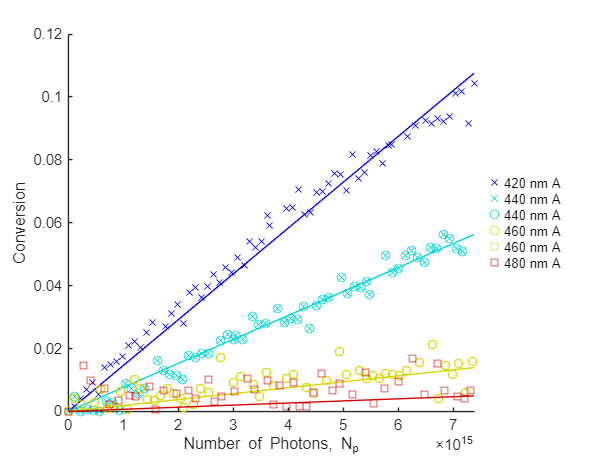

    %graphing kinetics, add section break here for running this section after edits without rerunning first section
    
    %initial linear kinetic with fits shown
    figure;
    hold on;

    for n = 1:repeatSamples:numdata-2
        currentItem = str2num(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 

        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;

        linscat = scatter(Np{n}, Conversion{n}, "x", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
        linfig = plot(p{n});
        set(linfig, Color=colorToUse);
        set(linfig(1), 'Visible','off');
        set(linfig(3), 'Visible','off');
        set(get(get(linfig(1), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
        set(get(get(linfig(2), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
        set(get(get(linfig(3), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
    end    
    for n = 2:repeatSamples:numdata-1
        currentItem = str2num(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 

        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;

        linscat = scatter(Np{n}, Conversion{n}, "o", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
        linfig = plot(p{n});
        set(linfig, Color=colorToUse);
        set(linfig(1), 'Visible','off');
        set(linfig(3), 'Visible','off');
        set(get(get(linfig(1), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
        set(get(get(linfig(2), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
        set(get(get(linfig(3), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
    end   
    for n = 3:repeatSamples:numdata
        currentItem = str2num(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 

        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;

        linscat = scatter(Np{n}, Conversion{n}, "square", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
        linfig = plot(p{n});
        set(linfig, Color=colorToUse);
        set(linfig(1), 'Visible','off');
        set(linfig(3), 'Visible','off');
        set(get(get(linfig(1), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
        set(get(get(linfig(2), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
        set(get(get(linfig(3), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
    end   

    xlabel("Number of Photons, N_{p}", Interpreter="tex");
    ylabel("Conversion");
    xlim([0 Np{1}(linvec(1))]) %use if linvec
    %xlim([0 Ktime{n}*increment{n}*timestepSet+0.01]); %use if Ktime
    % ylim([0 inf]);
    title("")
    %title("Initial Kinetics of " + Sample);
    legend("Location","eastoutside", box="off")
    hold off;

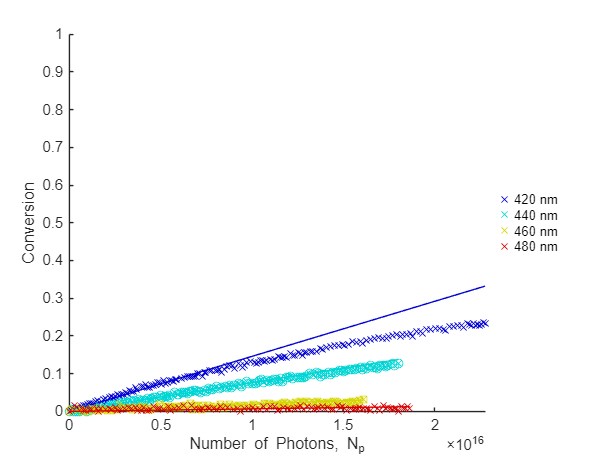



    %full kinetic with initial linear fits shown
    figure;
    hold on;
    
    colormap(jet);
    
    if iscellstr(excitationWLs)
      uniqueExcitationWLs = cellfun(@str2num, unique(excitationWLs));
    else
      uniqueExcitationWLs = unique(excitationWLs);
    end
    numUniqueWLs = numel(uniqueExcitationWLs);
    
    for n = 1:3:numdata-2
        currentItem = str2num(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 

        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;

        linscat = scatter(Np{n}, Conversion{n}, "x", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
        extendFit = predict(p{n}, transpose(Np{n}));
        linfigExt = plot(Np{n}, extendFit);
        set(linfigExt, Color=colorToUse);
        %set(linfigExt(1), 'Visible','off');
        set(get(get(linfigExt(1), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
    end    
    for n = 2:3:numdata-1
        currentItem = str2num(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 

        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;

        linscat = scatter(Np{n}, Conversion{n}, "o", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
        extendFit = predict(p{n}, transpose(Np{n}));
        linfigExt = plot(Np{n}, extendFit);
        set(linfigExt, Color=colorToUse);
        %set(linfigExt(1), 'Visible','off');
        set(get(get(linfigExt(1), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
    end   
    for n = 3:3:numdata
        currentItem = str2num(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 

        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;

        linscat = scatter(Np{n}, Conversion{n}, "square", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
        extendFit = predict(p{n}, transpose(Np{n}));
        linfigExt = plot(Np{n}, extendFit);
        set(linfigExt, Color=colorToUse);
        %set(linfigExt(1), 'Visible','off');
        set(get(get(linfigExt(1), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
    end   

    n=1;
    legendEntries = [];
    legendNames = {};
    for n = 1:repeatSamples:numdata
        currentItem = str2double(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 
        name{n} = [excitationWLs{n}  ' nm '];
        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;
        h = scatter(Np{n}, Conversion{n}, "x", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
        legendEntries = [legendEntries, h];
        legendNames = [legendNames, name{n}];
        extendFit = predict(p{n}, transpose(Np{n}));
        linfigExt = plot(Np{n}, extendFit);
        set(linfigExt, Color=colorToUse);
        %set(linfigExt(1), 'Visible','off');
        set(get(get(linfigExt(1), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
    end

        hold off;

    xlabel("Number of Photons, N_{p}");
    ylabel("Conversion") %at " + wavePos + " nm");
    xlim([0 inf]);%length(time{n})*increment{n}+0.01]);
    ylim([0 1]);
    %title("Kinetics of " + Sample);
    legend(legendEntries, legendNames, "Location","eastoutside", box="off")

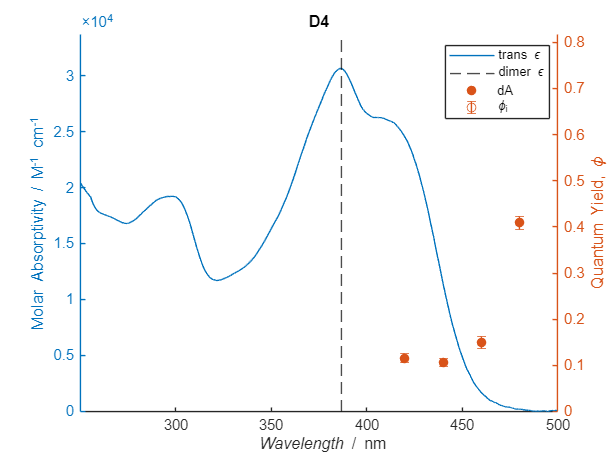

%calculations and more graphs section
AbsAPAv = zeros(length(FirstAbsEach{1}),1);
samples = zeros(length(numdata));
InitialGradientEach = zeros(length(numdata));

%create averaged absorbance from the initial absorbance of each experiment
for aa = 1:numdata
    AbsAPAv = AbsAPAv + FirstAbsEach{aa};
    samples(aa) = sampleID{aa};
end
AbsAPAv = AbsAPAv/numdata;
AbsAPAvA = AbsAPAv;
AbsAPAv = (AbsAPAv - min(AbsAPAv))/(initialConcentration*2); %factor of 2 for tethered molecule

%loop through each linear kinetic rate, save and create a matrix, average data over triplicate and create error based on triplicate
    for u = 1:numdata
        InitialGradientEach(u) = gradient{u};
        avgExWaveAP(u) = ExWaveAP{u};
    end

    InitialGradientMatrix = reshape(InitialGradientEach, repeatSamples, []);
    InitialGradientAvg = mean(InitialGradientMatrix,1);
    InitialGradientUpperError = max(InitialGradientMatrix,[],1) - InitialGradientAvg;
    InitialGradientLowerError = InitialGradientAvg - min(InitialGradientMatrix,[],1);

    avgExWaveAP = reshape(avgExWaveAP, [], numUniqueWLs);
    UniqueExWaveAP = avgExWaveAP(1,:);

    %If laser power file exists, can do quantum yields and add error from laser power std d
if exist(fullfile(folderPath, fileNameLaserPower), 'file')
    PhotonErrorMean = transpose(sqrt((LaserPulseErrorBefore(1:numdata)./LaserPulseEBefore(1:numdata)).^2+(LaserPulseErrorAfter(1:numdata)./LaserPulseEAfter(1:numdata)).^2));
    PhotonErrorMatrix = reshape(PhotonErrorMean(1,1:numdata), repeatSamples, []);
    PhotonErrorAvg = mean(PhotonErrorMatrix,1);
    %Photon flux equations 
    exwavelengths = cell2mat(EPhotonWL);
    PhotonFlux = (transpose(PhotonEnergyMean).*(10^-6)*20.*exwavelengths)./((6.626*10^-34)*(299792458));
    PhotonFluxMatrix = reshape(PhotonFlux(1,1:numdata), repeatSamples, []);
    PhotonFluxAvg = mean(PhotonFluxMatrix,1);
    InitialGradientUpperError = (sqrt((InitialGradientUpperError./InitialGradientAvg).^2 + PhotonErrorAvg.^2)).*InitialGradientAvg; %total error from sample variance and photon std d
    InitialGradientLowerError = (sqrt((InitialGradientLowerError./InitialGradientAvg).^2 + PhotonErrorAvg.^2)).*InitialGradientAvg; %total error from sample variance and photon std d

    for a = 1:numdata/repeatSamples
        [~, WLLocation] = min(abs(croppedwavelengthColumn - UniqueExWaveAP(a)));
        TransEpsatWL(a) = AbsAPAv(WLLocation);
        TransAatWL(a) = AbsAPAvA(WLLocation);
    end

    %calculate quantum yield
QYki = (InitialGradientAvg.*initialConcentration*2)*(volume)*(AvNum)./(2*(1-(10.^(-TransEpsatWL.*initialConcentration*2*pathlength))));
QYkiEq3 = InitialGradientAvg./(PhotonFluxAvg.*(TransEpsatWL*log(10)*10^3)/AvNum);
QYkiLowerError = sqrt((InitialGradientLowerError./InitialGradientAvg).^2+PhotonErrorAvg.^2).*QYki;
QYkiUpperError = sqrt((InitialGradientUpperError./InitialGradientAvg).^2+PhotonErrorAvg.^2).*QYki;

%plot quantum yield
figure
hold on
yyaxis left
plot(croppedwavelengthColumn, AbsAPAv(:,:), LineStyle="-");
xline(wavelengthColumn(waveIndex,1), LineStyle="--",Color='k');
hold off
ylabel('Molar Absorptivity / M^{-1} cm^{-1}');
ymax1 = max(AbsAPAv);
ylim([0 ymax1+ymax1/10])
yyaxis right
ymax3 = max(QYki);
hold on
plot(UniqueExWaveAP, QYki, 'o', 'color', '#D95319', 'MarkerFaceColor', '#D95319');
errorbar(UniqueExWaveAP, QYki, QYkiLowerError, QYkiUpperError, 'o', 'color', '#D95319');
hold off
xlim([wavelengthColumn(closestStartWLIndex) wavelengthColumn(closestEndWLIndex)])
xlabel('{\it Wavelength} / nm');
ylabel('Quantum Yield, \phi');
xlim([wavelengthColumn(closestStartWLIndex) wavelengthColumn(closestEndWLIndex)])
ylim([0 ymax3*2])
%title(Solventname);
title(Sample)
legend("trans \epsilon","dimer \epsilon", "dA", "\phi_{i}", "Location","best")

end

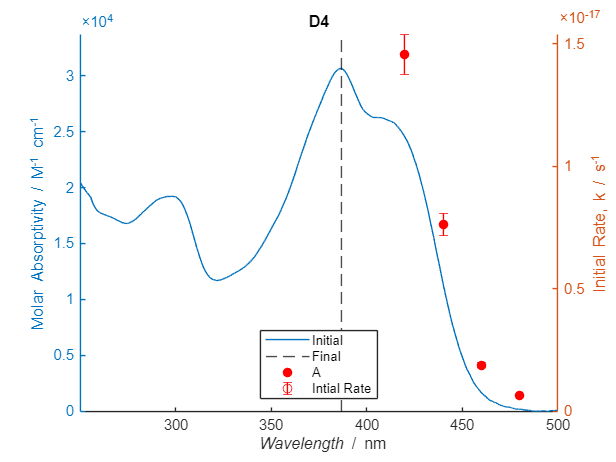


%plot initial rates
    figure;
        yyaxis left
        hold on
        plot(croppedwavelengthColumn, AbsAPAv(:,:));
        xline(wavelengthColumn(waveIndex,1), LineStyle="--",Color='k');
        ylabel('Molar Absorptivity / M^{-1} cm^{-1}');
        xlim([str2double(StartABSWL) str2double(EndABSWL)])
        ymax1 = max(AbsAPAv);
        ylim([0 ymax1+(ymax1/10)])
        hold off
        yyaxis right
        hold on;
        plot(UniqueExWaveAP, InitialGradientAvg, 'o', 'color', 'r', 'MarkerFaceColor', 'r');
        errorbar(UniqueExWaveAP, InitialGradientAvg, InitialGradientLowerError, InitialGradientUpperError, 'o', 'color', 'r');
        hold off;
        xlabel('{\it Wavelength} / nm');
        ylabel("Initial Rate, k / s^{-1}");
        ylim([0 inf])
        xlim([wavelengthColumn(closestStartWLIndex) wavelengthColumn(closestEndWLIndex)])
        %title(Solventname);
        title(Sample)
        legend("Initial", "Final", "A", "Intial Rate", "Location","best")

%GUI code
function variables = GUIScript()

    fig = uifigure('Name', 'Please fill out the entries below', 'Position', [100, 100, 400, 350]);

    options = {'Action Plot', 'Abs Plots'};
    concentrationOptions = {'M', 'mM', 'uM', 'nM'};
    numOptions = numel(options);
    variables = struct();

    checkBoxLabel = uilabel(fig, 'Text', 'Show:', 'Position', [230, 320, 150, 22]);
    checkboxWidth = 120;
    checkboxHeight = 22;
    checkboxes = gobjects(1, numOptions);
    for i = 1:numOptions
        checkboxes(i) = uicheckbox(fig, 'Text', options{i}, 'Position', [230, 320 - 25 * i, checkboxWidth, checkboxHeight]);
    end
    
    textbox1Label = uilabel(fig, 'Text', 'Sample name:', 'Position', [50, 300, 150, 22]);
    textbox1 = uitextarea(fig, 'Position', [50, 280, 150, 22]);

    textbox2Label = uilabel(fig, 'Text', 'Solvent used:', 'Position', [50, 250, 100, 22]);
    textbox2 = uitextarea(fig, 'Position', [50, 230, 100, 22]);

    textbox3Label = uilabel(fig, 'Text', 'Concentration:', 'Position', [50, 200, 80, 22]);
    textbox3 = uitextarea(fig, 'Position', [50, 180, 50, 22]);
    
    textbox4Label = uilabel(fig, 'Text', 'Start WL:', 'Position', [180, 200, 60, 22]);
    textbox4 = uitextarea(fig, 'Position', [180, 180, 60, 22]);
    
    textbox5Label = uilabel(fig, 'Text', 'End WL:', 'Position', [250, 200, 60, 22]);
    textbox5 = uitextarea(fig, 'Position', [250, 180, 60, 22]);

    textbox6Label = uilabel(fig, 'Text', 'dA WL:', 'Position', [320, 200, 60, 22]);
    textbox6 = uitextarea(fig, 'Position', [320, 180, 60, 22]);
    
    textbox7Label = uilabel(fig, 'Text', 'Kinetic Time:', 'Position', [180, 150, 80, 22]);
    textbox7 = uitextarea(fig, 'Position', [180, 130, 60, 22]);

    textbox8Label = uilabel(fig, 'Text', 'Total Time:', 'Position', [250, 150, 80, 22]);
    textbox8 = uitextarea(fig, 'Position', [250, 130, 60, 22]);

    dropdownLabel = uilabel(fig, 'Text', '', 'Position', [100, 200, 50, 22]);
    dropdown = uidropdown(fig, 'Items', concentrationOptions, 'Position', [100, 180, 50, 22]);
    
    confirmButton = uibutton(fig, 'Text', 'Confirm', 'Position', [50, 20, 70, 30], 'ButtonPushedFcn', @(btn, event) confirmSelection());
    cancelButton = uibutton(fig, 'Text', 'Cancel', 'Position', [130, 20, 70, 30], 'ButtonPushedFcn', @(btn, event) cancelSelection());
    showSpecButton = uibutton(fig, 'Text', 'Show Spectrum', 'Position', [210, 20, 70, 30], 'ButtonPushedFcn', @(btn, event) spectrumSelection());

    loadState();
    
    function confirmSelection()
        variables.absorptionYN = checkboxes(1).Value;
        variables.plotsYN = checkboxes(2).Value;

        variables.SampleName = textbox1.Value;
        variables.SolventName = textbox2.Value;
        variables.ConcentrationNum = textbox3.Value;
        variables.StartWL = textbox4.Value;
        variables.EndWL = textbox5.Value;
        variables.WavePosition = textbox6.Value;
        variables.KinTime = textbox7.Value;
        variables.TotalTime = textbox8.Value;

        variables.SelectedUnit = dropdown.Value;
        
        save('guiStateDimer.mat', 'variables');
        close(fig);
    end

    function cancelSelection()
        disp('Aborted');
        close(fig);
        variables = [];
        return;
    end

    
    function loadState()
        if exist('guiStateDimer.mat', 'file')
            load('guiStateDimer.mat', 'variables');
            
            checkboxes(1).Value = variables.absorptionYN;
            checkboxes(2).Value = variables.plotsYN;

            textbox1.Value = variables.SampleName;
            textbox2.Value = variables.SolventName;
            textbox3.Value = variables.ConcentrationNum;
            textbox4.Value = variables.StartWL;
            textbox5.Value = variables.EndWL;
            textbox6.Value = variables.WavePosition;
            textbox7.Value = variables.KinTime;
            textbox8.Value = variables.TotalTime;

            dropdown.Value = variables.SelectedUnit;
        end
    end
    
    movegui(fig, 'center');
    uiwait(fig);

end






